# Segundo entrega: Reconocimiento de digitos hablados

Para nuestro primer avance tuvimos dos aproximaciones para resolver el problema. 

La primera consistía en entrenar un modelo de machine learning a partir de un dataset propio de los digitos hablados.


X = []; %inicializas tu vector vacio
y = []; %inicializas tu vector de etiquetas


%augmenter = audioDataAugmenter(...
%    "AugmentationMode","sequential", ... 
%    "TimeStretchProbability",0);


TL = 256e-3;
L = TL*8000;
overlap= floor(10e-3*8000);
% Tus muestras del número 0
for i=1:401
    [audio, Fs] = audioread("dataset\0\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y; 0]; %ETIQUETAS a esta muestra con el "0"
end

% Tus muestras del número 1
for i=1:401
    [audio, Fs] = audioread("dataset\1\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y; 1]; %ETIQUETAS a esta muestra con el "1"
end

for i=1:401
    [audio, Fs] = audioread("dataset\2\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y; 2]; %ETIQUETAS a esta muestra con el "2"
end

for i=1:401
    [audio, Fs] = audioread("dataset\3\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y;3]; %ETIQUETAS a esta muestra con el "3"
end

for i=1:401
    [audio, Fs] = audioread("dataset\4\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y; 4]; %ETIQUETAS a esta muestra con el "4"
end

for i=1:401
    [audio, Fs] = audioread("dataset\5\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y; 5]; %ETIQUETAS a esta muestra con el "5"
end

for i=1:401
    [audio, Fs] = audioread("dataset\6\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y; 6]; %ETIQUETAS a esta muestra con el "6"
end

for i=1:401
    [audio, Fs] = audioread("dataset\7\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y; 7]; %ETIQUETAS a esta muestra con el "7"
end

for i=1:401
    [audio, Fs] = audioread("dataset\8\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y; 8]; %ETIQUETAS a esta muestra con el "8"
end

for i=1:401
    [audio, Fs] = audioread("dataset\9\"+i+".wav");
    audio=normalizar(audio);
    N= length(audio);
    r_audio= audio .* hamming(N);
    coeff = mfcc(r_audio,Fs,Window=hamming(L),OverlapLength=overlap); % calculas su mfcc.wav
    coeffflat = reshape(coeff,[1 4*14]); % lo pasas a un vector
    X = [X;coeffflat]; % almacenas en una matriz de muestras
    y = [y; 9]; %ETIQUETAS a esta muestra con el "9"
end

size(X)

ans =         4010          56


%num_filas = num_muestras
%num_columnas = num_caracteristicas

size(y)

ans =         4010           1


%num_filas = num_muestras
%num_columnas = 1 (solo un numero que indica la etiqueta)

%Particionamos los datos
cv = cvpartition(y, 'holdout', .2);

xt = cv.training;
Xtrain = X(cv.training,:);
Ytrain = y(cv.training,1);

Xtest = X(cv.test,:);
Ytest = y(cv.test,1)

Ytest =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


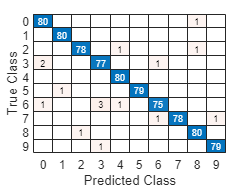


%Entrenamiento
mdl = fitensemble(Xtrain,Ytrain,'bag',200,'tree','type','Classification');
%Prueba de modelo
ypred = predict(mdl,Xtest);

confusionchart(Ytest,ypred)

## Una segunda aproximación fue a través de una análisis frecuencial a través de la transformada de fourier

En esta ocasión realizamos las pruebas mediante algunos datos almacenados que corresponden con la voz del usuario actual.

%Grabamos la voz del usuario
Fs=8000;
t=2;
nbits=16;
nChannel=1;
sig = audiorecorder(Fs, nbits, nChannel);
disp('Grabando...');

Grabando...


recordblocking(sig,t);
voz_usuario = getaudiodata(sig);
disp('Grabado!');

Grabado!



disp('Reconocimiento de voz Número');

Reconocimiento de voz Número


% Leemos los audios
v = [];
for i=0:9
    v(:,i+1) = audioread("valor"+i+".wav");
end

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 137)
    [y, Fs] = readaudio (filename, range, datatype);


%Normalizamos
numero = normalizar(v);
for i=0:9
    numero(:,i+1) = normalizar(v(:,i+1));
end
%Aplicamos la transformada de fourier para el análisis frecuencial

transformar = mfcc(numero, Fs);

usuario = normalizar(voz_usuario);
transformarUsuario = mfcc(usuario,Fs);

%Calculamos el error con cada muestra
for i=0:9
    error(i+1) = norm(transformarUsuario-transformar(:,:,i+1));
end
%Calculamos la mínima distancia
min_error = min(error);

switch min_error
    case error(1)
        disp('Número Cero');
    case error(2)
        disp('Número UNO');
    case error(3)
        disp('Número DOS');
    case error(4)
        disp('Número TRES');
    case error(5)
        disp('Número CUATRO');
    case error(6)
        disp('Número CINCO');
    case error(7)
        disp('Número SEIS');
    case error(8)
        disp('Número SIETE');
    case error(9)
        disp('Número OCHO');
    case error(10)
        disp('Número NUEVE');
end